# GRID AND MERGE DATA for OSNAP mooring

***Original author: Lewis Drysdale, 2020***


clearvars -except pathosnap pathgit ; close('all')


### 1.SET GRID AND QA PARAMETERS

p_hydrogrid.dum         = -9999.0000;
p_hydrogrid.c1535       = 42.914;
p_hydrogrid.mcat        = [332:337];    % instrument model numbers
p_hydrogrid.int_step    = 10;           % vertical interpolation step
p_hydrogrid.preverse    = 4000;         % 4000 pressure level below whch deep temperature reversion may occur


### 2.REPAIR AND DESPIKE SETTINGS

p_hydrogrid.gap_max      = 10;          % allow for a maximum of gap [days] in data to interpolate across
p_hydrogrid.y_tol        = [-10 10];    % deviation in PSU allowed by depsike routine
p_hydrogrid.stddy_tol    = 4;           % tolerance range of differences between adjacent values of y
p_hydrogrid.nloop        = 5;           % despike loop number
p_hydrogrid.graphics     = 'y';
p_hydrogrid.distrangectd = 100e3;       % distance of the reference ctd from the mooring - UNUSED


### 3.GRID INITIALISATION

% CURRENTLY DEFINED IN INI FOLDER .DAT FILE. FUNCTION
p_hydrogrid.p_gridsize   = 20;
p_hydrogrid.v_interp     = 'linear';
p_hydrogrid.co           = 1/2; % filter cut off frequency [1/days]
p_hydrogrid.iss          = 12; % initial sub-sampling frequency [1/days]
p_hydrogrid.fss          = 2;  % final sub-sampling frequency [1/days]


### 4.SET DIRECTORIES FOR MERGE

hydrodir                = [pathosnap filesep 'data/moor/proc/hydro_grid/'];
grdatdir                = [pathosnap filesep 'data/moor/proc/hydro_grid_merged/'];
boundarydir             = [pathgit filesep 'exec/gitrepo/stage3/gridding/MCAT/DAT/'];


### 5.MERGE INITIALISATION 

gridding                = 1  ;  % 1: linear, 2: using climatological profiles
bathy                   = false ;  % turns on/off the bathy charts. off = flase
mc_check_plot           = true; %false ;  % turns on/off the microcat check plots. off =false

jg_start                = datenum(2014,6,01,00,00,00);
jg_end                  = datenum(2022,31,07,00,00,00);

lastyeardata            = '2020';

JG                      = jg_start: 0.5: jg_end; % full time series using 2 samples per day
pgg                     = 0:20:2000; % depths in 20dbar bins
depthminforhoriz_interp = 40; % in case no data are available at a specific time
% (e.g.: mooring turn around, knock-down of the mooring head) don't interpolate on a time basis for level above 40 m


### MOORING FILE NAMES 

### UPDATE NEW MOORING FILES HERE 

### path of the mooring data is defined in the startup file under osnap/


moorings = {'rteb1_01_2014';...
            'rtwb1_01_2014';...
            'rtwb2_01_2014';...
            'rtwb1_02_2015';...
            'rtwb2_02_2015';...
            'rteb1_02_2015';...
            'rtwb1_03_2016';...
            'rtwb2_03_2016';...
            'rteb1_03_2016';...
            'rtwb1_04_2017';...
            'rtwb2_04_2017';...
            'rteb1_04_2017';...
            'rtwb1_05_2018';...
            'rtwb2_05_2018';...
            'rteb1_05_2018';...
            'rtwb1_06_2020';...
            'rtwb2_06_2020';...
            'rteb1_06_2020'};
        
% order of microCATs (serial numbers 335:337) in info.dat file, but exclude ODO 
microcat_order=(   {[1:4 6:8],...
                    [1:8],...
                    [1:2],...
                    [1:8],...
                    [1:2],...
                    [1:8],...
                    [1:8],...
                    [1:2],...
                    [1 3:8],...
                    [1:9],...
                    [1:2],...
                    [2:6 9:11 13],...
                    [1:9],...
                    [1:3],...
                    [1:5 8:12] ...
                    [1:9] ...
                    [1:3] ...
                    [1:3 5 8:12]});
instrument_order=(  {[1:4 6:8],...
                    [1:8],...
                    [1:2],...
                    [1:8],...
                    [1:2],...
                    [1:8],...
                    [1:8],...
                    [1:2],...
                    [1 3:8],...
                    [1:9],...
                    [1:2],...
                    [2:6 9:11 13],...
                    [9140 14355 3481 11329 10559 14368 11337 14353 14354],...
                    [9377 3218 9372],...
                    [11290 11289 11288 11287 10577 3276 10560 10562 9113 9375],...
                    [11343,11342,14364,7923,7924,11137,11139,10576,11465],...
                    [10575,11341,13020],...
                    [9141,11322,9396,11327,11330,11334,11335,9390,11338]});

                


### CHECK FOR FOLDERS 

for ii=1:numel(moorings)
    if exist([pathosnap '/Figures/' char(moorings(ii))],'dir')==7
    else
        mkdir([pathosnap '/Figures/' char(moorings(ii))])
    end
end


## GRID AND MERGE 

gridans = questdlg(['Grid or merge moorings?'],...
    'Grid and merge',...
    'Grid','Merge','Merge');
% Handle response
switch gridans

case 'Grid'

    [indx,tf] = listdlg('PromptString',{'Select the moorings for interpolation.',...
        '',''},...
        'ListString',moorings);
    if tf==1
        mlist=moorings(indx);
        ilist=microcat_order(indx);
        tlist=instrument_order(indx);
    else
        disp('No mooring selected');
    end

for ii=1:numel(indx) % for each mooring to process

moor=mlist{ii}; % select the first moooring to process

p_hydrogrid.mc_ind=cell2mat(ilist(ii)); % get instrument order


*** if there is a requirement to process uncalibrtaed data make next line uncommented, and update serial numbers above ***

p_hydrogrid.mc_int=cell2mat(tlist(ii)); %get instrument list
% p_hydrogrid.mc_int=[]; % get instrument list


### SET PATHS

p_hydrogrid.basedir      = pathosnap;
p_hydrogrid.moor         = moor;
p_hydrogrid.ini_path     = [p_hydrogrid.basedir '/data/moor/proc/hydro_grid/ini'];
p_hydrogrid.rodbpath     = [p_hydrogrid.basedir '/data/moor/'];
p_hydrogrid.rodbctdpath  = [p_hydrogrid.basedir '/cruise_data/'];
p_hydrogrid.info_path    = [p_hydrogrid.rodbpath,'proc/',moor,'/'];
p_hydrogrid.mooringpath  = [pathosnap '/data/moor/proc'];
p_hydrogrid.out_path     = [p_hydrogrid.basedir '/data/moor/proc/hydro_grid/'];
p_hydrogrid.outname      = [moor,'_grid.mat'];
p_hydrogrid.dataexternal_ctd_dir        = [p_hydrogrid.basedir '/cruise_data/'];
p_hydrogrid.datactd_ref_cruises   = {'kn221';'pe399'}; % for plot


### INTERPOLATE 

- no use of TS climatology to get salinities where the sal. record is completely useless

- no guess of  the course of the profiles between the vertical grid points

- ini file no longer required

hydro_grid_osnap_linear_interp(p_hydrogrid);
end

###  OPTIONS TO MERGE 

Continue Merging.


---------  OSNAP 1 (KN221 --> PE399) ---------


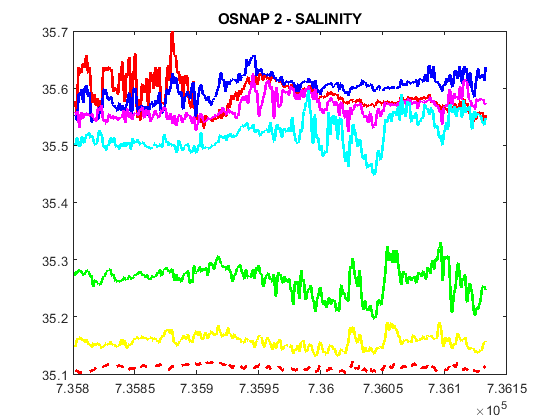

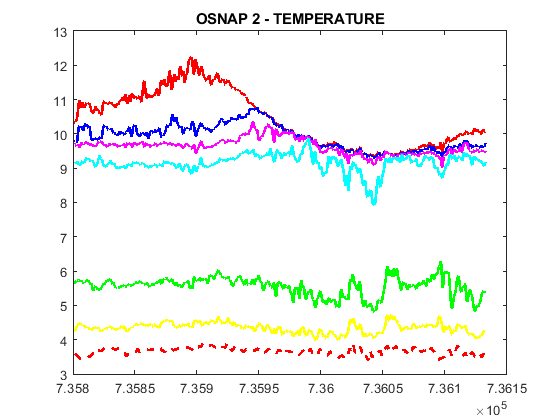

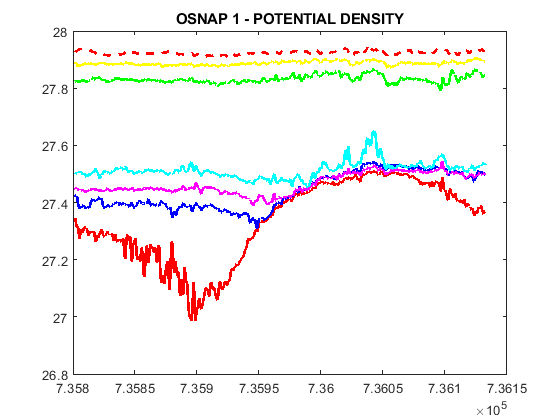

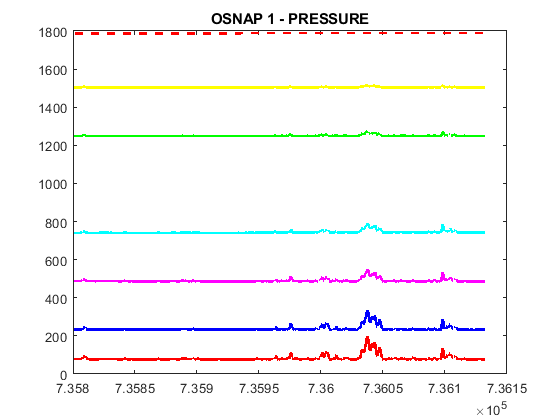

---------  OSNAP 2 (PE399 --> DY053) ---------


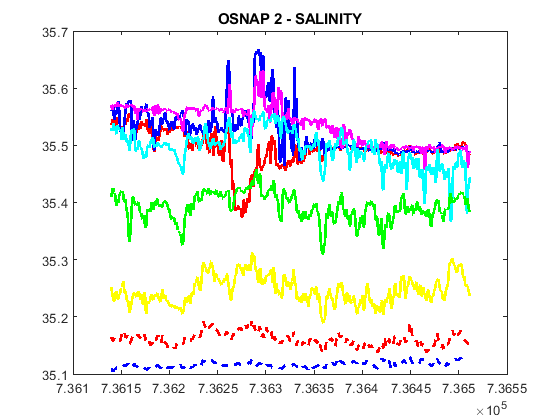

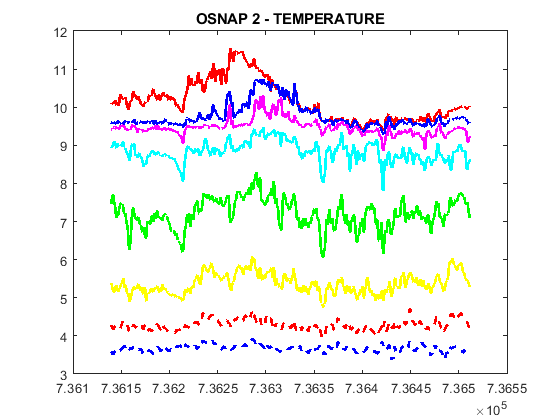

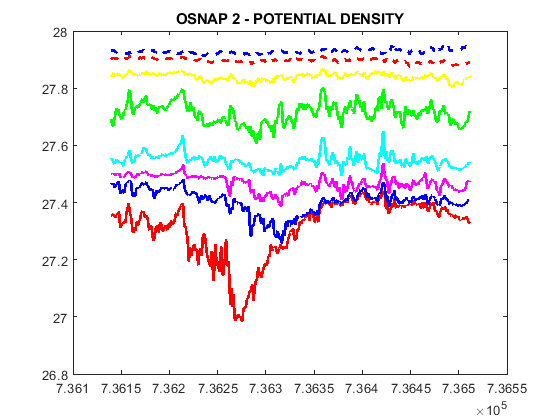

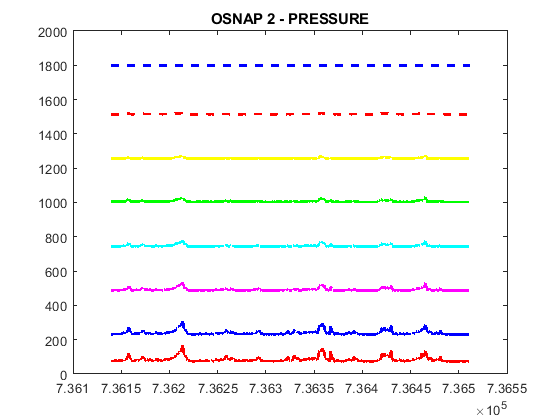

---------  OSNAP 3 (DY053--> DY078) ---------


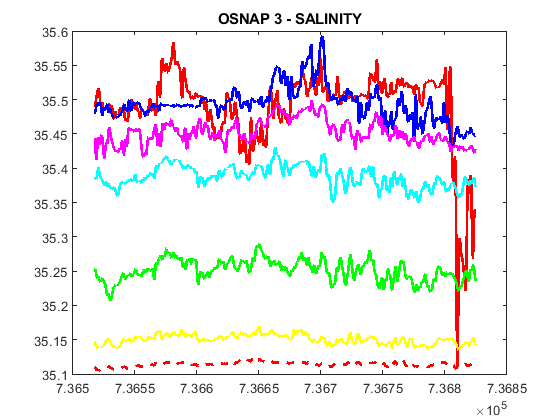

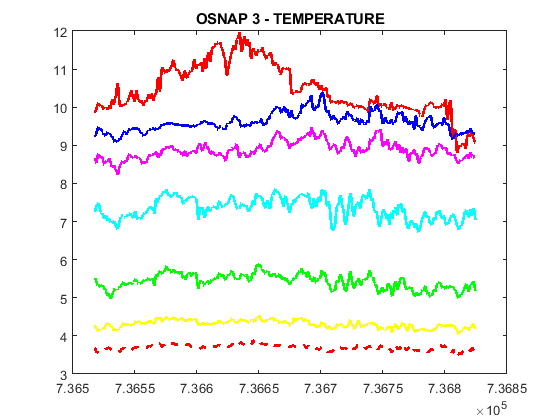

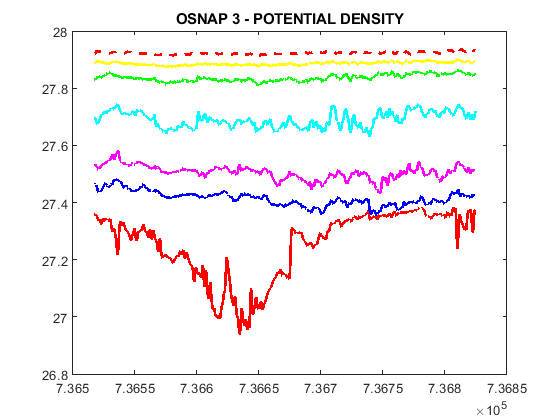

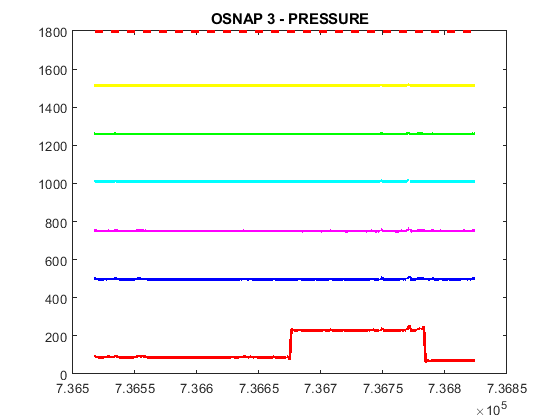

---------  OSNAP 4 (DY078--> AR30) ---------


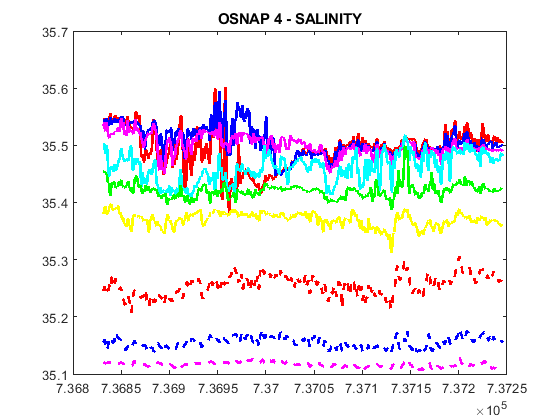

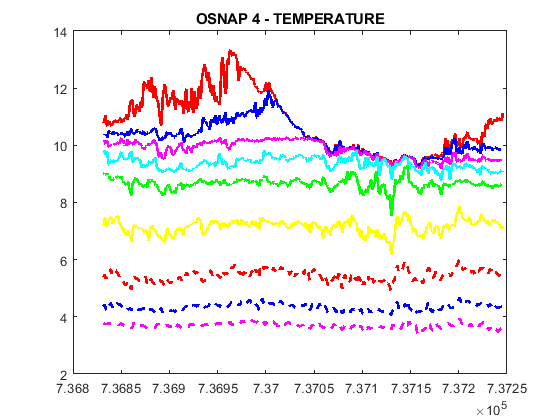

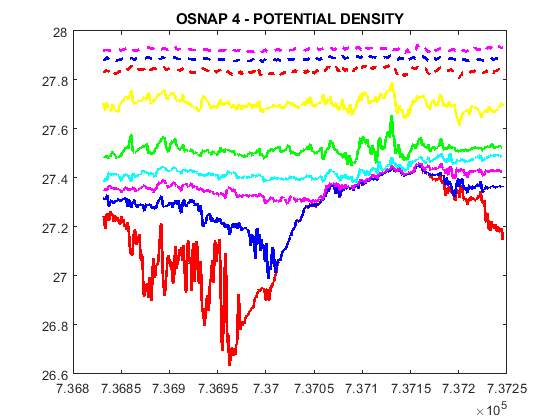

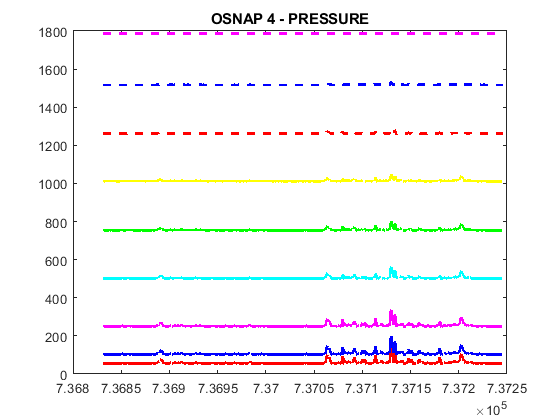

---------  OSNAP 5 (AR30--> DY120) ---------


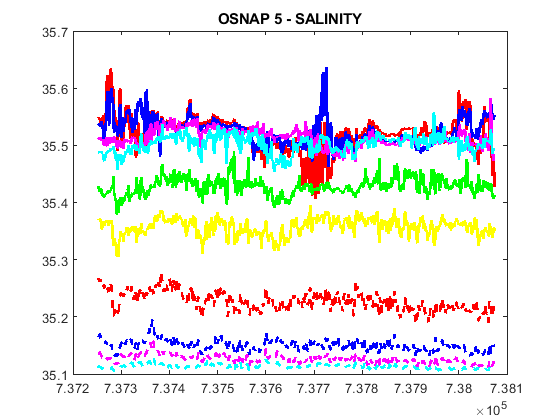

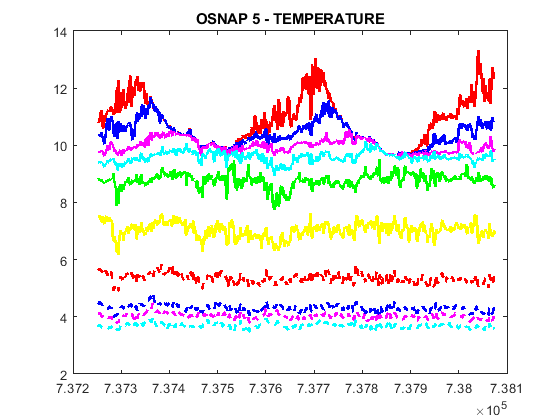

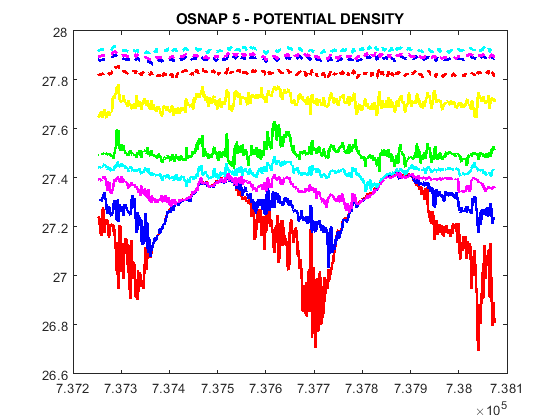

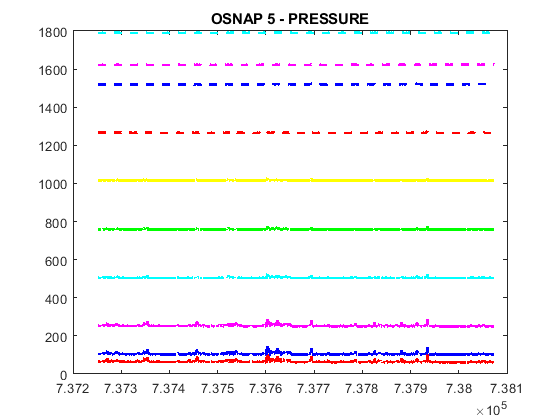

---------  OSNAP 6 (DY120--> JC238) ---------


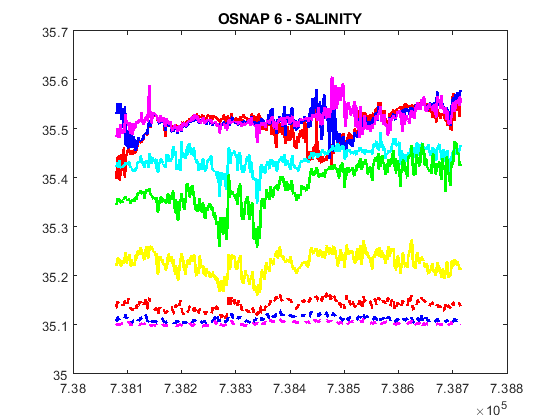

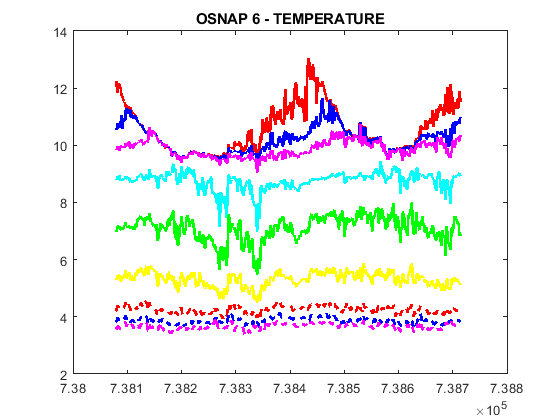

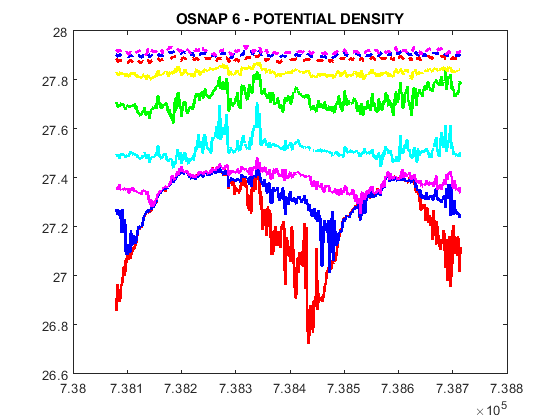

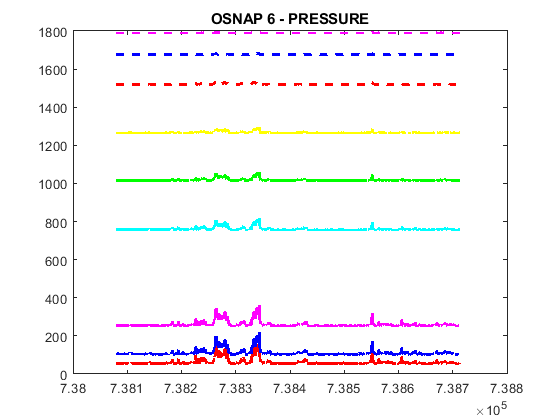

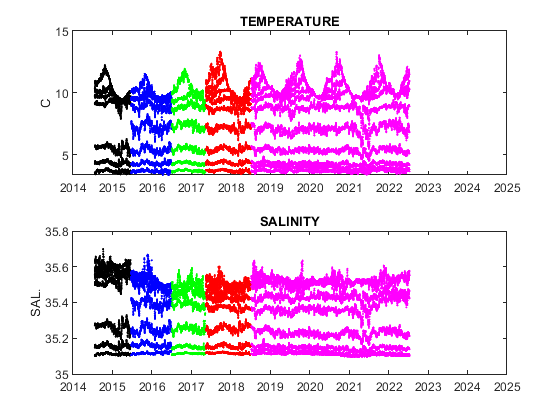

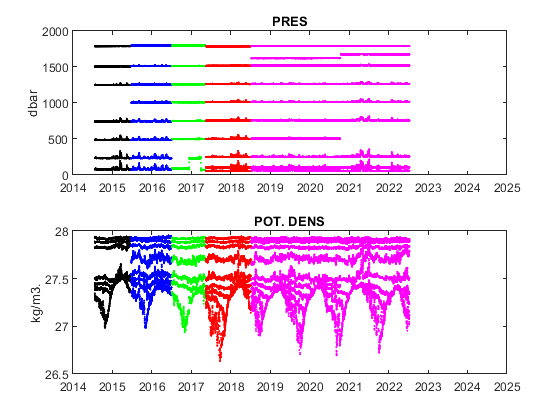

saving: RTEB_merg_linear_interp_2020.mat


no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
loop: 1;  spikes: 0


loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 1
loop: 2;  spikes: 1
loop: 3;  spikes: 1
loop: 4;  spikes: 1
loop: 5;  spikes: 1


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


no more spikes found after loop cycle 5


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


loop: 1;  spikes: 0
loop: 2;  spikes: 0
loop: 3;  spikes: 0
loop: 4;  spikes: 0
loop: 5;  spikes: 0


no more spikes found after loop cycle 5


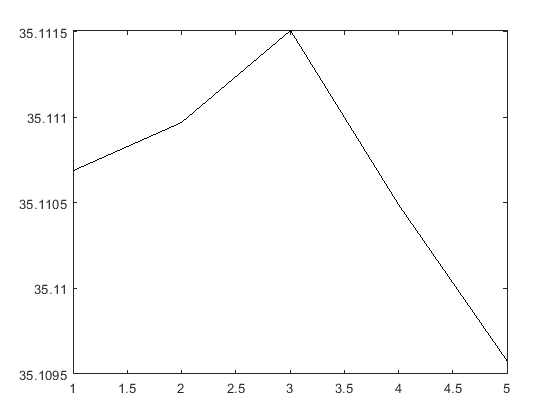

no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5
no more spikes found after loop cycle 5


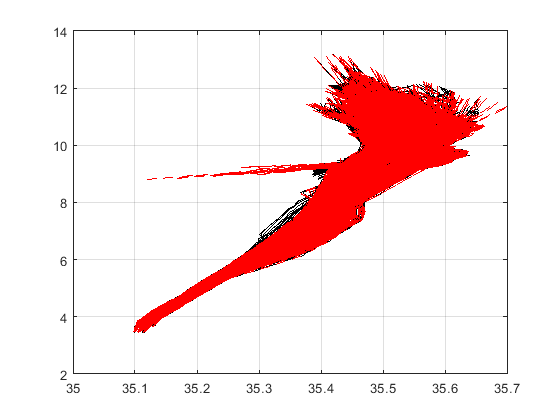

Error using save
Variable 'RTEB_merg_20220818T153649' not found.
Error in merge_osnap_data_east (line 666)
save([grdatdir outputfile],['RTEB_merg_' datestr(now, 30)]);
Error in run (line 91)
evalin('caller', strcat(script, ';'));

answer = questdlg(['Do you want to merge data?'], ...
    'Merge',...
    'Yes','No','No');
% Handle response
switch answer
    case 'Yes'
   [indx,tf] = listdlg('PromptString',{'Select moorings for merge.',...
        'Make sure only western or eastern arrays are selected',''},...
        'ListString',moorings);
    if tf==1
        moor=moorings(indx);
    else
        disp('No moorings selected');
    end

    % change file naming convention for .dat files by inclduing 'osnap' in
    % file name and removing number after rteb
    for ii=1:numel(moor)
       moor{ii}=[moor{ii}(1:4) '_osnap' moor{ii}(6:end)];
    end

    moorstr=strjoin(moor,', ');
    answer = questdlg(['Merge moorings : ' moorstr '?'], ...
        'Merge',...
        'Continue','Cancel','Wrong moorings','Wrong moorings');
    % Handle response
    switch answer
        case 'Continue'
            disp([answer ' Merging.'])
            if ismember(moor{1}(3:4),'eb')
                run merge_osnap_data_east.mlx
            else
                run merge_osnap_data_west.mlx
            end
    case 'Cancel'
        case 'Wrong moorings'
            [indx,tf] = listdlg('PromptString',{'Select moorings for merge.',...
                'Make sure only western or eastern arrays are selected',''},...
                'ListString',moorings);
            if tf==1
                moor=moorings(indx);
            else
                disp('No moorings selected');
            end

            % change file naming convention for .dat files by inclduing 'osnap' in
            % file name
            for ii=1:numel(moor)
               moor{ii}=[moor{ii}(1:4) '_osnap' moor{ii}(6:end)];
            end

            disp([answer ' Merging.'])

            if ismember(moor{1}(3:4),'eb')
                run merge_osnap_data_east.mlx
            else
                run merge_osnap_data_west.mlx
            end

    end
       case 'No'
           return

end

% if merge only then prompt for files to merge.
case 'Merge'

    [indx,tf] = listdlg('PromptString',{'Select moorings for merge.',...
        'Make sure only western or eastern arrays are selected',''},...
        'ListString',moorings);
    if tf==1
        moor=moorings(indx);
    else
        disp('No moorings selected');
    end

    % change file naming convention for .dat files by inclduing 'osnap' in
    % file name and removing number after rteb
    for ii=1:numel(moor)
       moor{ii}=[moor{ii}(1:4) '_osnap' moor{ii}(6:end)];
    end

    moorstr=strjoin(moor,', ');
    answer = questdlg(['Merge moorings : ' moorstr '?'], ...
        'Merge',...
        'Continue','Cancel','Wrong moorings','Wrong moorings');
    % Handle response
    switch answer
        case 'Continue'
            disp([answer ' Merging.'])

            % if data is from western or eastern array, merge accordingly,
            % the difference is the way the data is indexed in the code,
            % and could probably do with an overhaul
            if ismember(moor{1}(3:4),'eb')
               run merge_osnap_data_east.mlx
            else
                run merge_osnap_data_west.mlx
            end

        case 'Cancel'
        case 'Wrong moorings'
            % re-select moorings
            [indx,tf] = listdlg('PromptString',{'Select moorings for merge.',...
                'Make sure only western or eastern arrays are selected',''},...
                'ListString',moorings);
            if tf==1
                moor=moorings(indx);
            else
                disp('No moorings selected');
            end

            % change file naming convention for .dat files by inclduing 'osnap' in
            % file name
            for ii=1:numel(moor)
               moor{ii}=[moor{ii}(1:5) '_osnap' moor{ii}(6:end)];
            end

            disp([answer ' Merging.'])

            if ismember(moor{1}(3:4),'eb')
                run merge_osnap_data_east.mlx
            else
                run merge_osnap_data_west.mlx

            end
    end
end